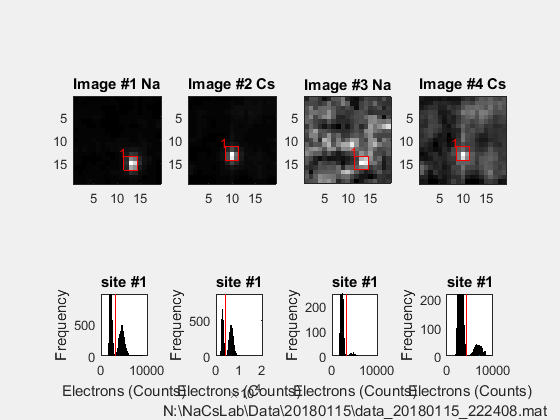

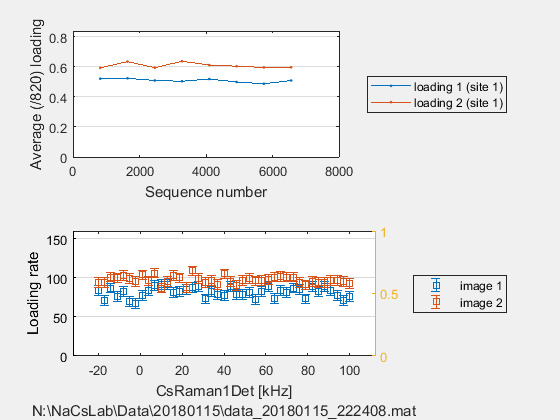

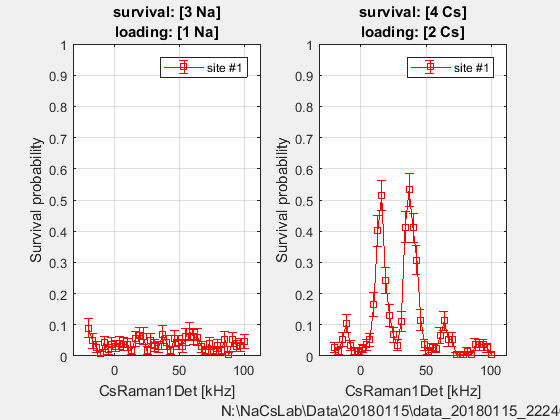

% Cs Ax2 Scan
d = replot2([20180115, 222408]);

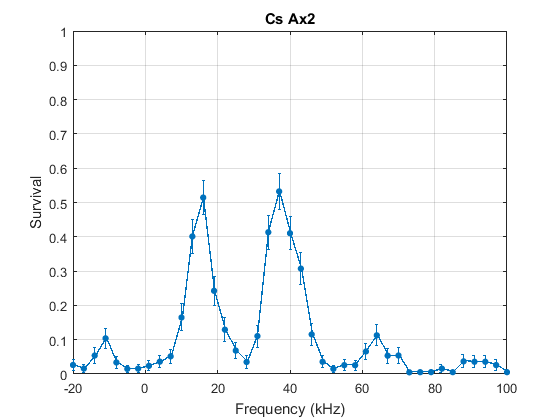



i=1; %which scan?
m=2; %which survival?

SurvProb = d(i).Analysis.SurvivalProbability;
SurvProbErr = d(i).Analysis.SurvivalProbabilityErr;
Params = d(i).Analysis.UniqueParameters;
SurvProb = SurvProb(m,:);
SurvProbErr = SurvProbErr(m,:);

figure(4); clf; set(gcf,'color','w');
errorbar( Params/1e3, SurvProb, SurvProbErr , '.-', 'CapSize', 2,...
    'Linewidth', 1, 'Marker', '.', 'MarkerSize', 14);
title('Cs Ax2');
xlabel('Frequency (kHz)');
ylabel('Survival');
grid on;
%set(gca,'fontsize', 14);
ylim([0 1]);

figure(4);
%% fit to Gaussian
ft = 'a*exp(-(x-b)^2/w^2) + os';
fitcenter = 15;
fitwidth = 20; 1e6;
startPoints = [1 fitcenter  0 50];  %a, b, os, w

fitrange = fitcenter + fitwidth*[-1/2 1/2];
xfit = Params/1e3;
exclude = xfit < min(fitrange) | xfit > max(fitrange);
fit_obj = fit(xfit', SurvProb', ft, ...
      'Start', startPoints, 'Exclude', exclude)

fit_obj =      General model:
     fit_obj(x) = a*exp(-(x-b)^2/w^2) + os
     Coefficients (with 95% confidence bounds):
       a =      0.4544  (0.3635, 0.5452)
       b =        15.2  (14.62, 15.78)
       os =     0.06964  (0.009001, 0.1303)
       w =       -4.04  (-5.159, -2.92)

xplot = linspace( max(fitrange(1), min(xfit)), min(fitrange(2), max(xfit)), 200);
hold on; plot(xplot, fit_obj(xplot), '-k'); hold off;

%% fit to Gaussian
ft = 'a*exp(-(x-b)^2/w^2) + os';
fitcenter = 38;
fitwidth = 20; 1e6;
startPoints = [1 fitcenter  0 50];  %a, b, os, w

fitrange = fitcenter + fitwidth*[-1/2 1/2];
xfit = Params/1e3;
exclude = xfit < min(fitrange) | xfit > max(fitrange);
fit_obj = fit(xfit', SurvProb', ft, ...
      'Start', startPoints, 'Exclude', exclude)

fit_obj =      General model:
     fit_obj(x) = a*exp(-(x-b)^2/w^2) + os
     Coefficients (with 95% confidence bounds):
       a =      0.5667  (0.1488, 0.9846)
       b =       37.86  (36.5, 39.22)
       os =    -0.04805  (-0.5063, 0.4102)
       w =      -6.985  (-13.19, -0.7749)

xplot = linspace( max(fitrange(1), min(xfit)), min(fitrange(2), max(xfit)), 200);
hold on; plot(xplot, fit_obj(xplot), '-k'); hold off;

%% fit to Gaussian
ft = 'a*exp(-(x-b)^2/w^2) + os';
fitcenter = 64;
fitwidth = 20; 1e6;
startPoints = [1 fitcenter  0 50];  %a, b, os, w

fitrange = fitcenter + fitwidth*[-1/2 1/2];
xfit = Params/1e3;
exclude = xfit < min(fitrange) | xfit > max(fitrange);
fit_obj = fit(xfit', SurvProb', ft, ...
      'Start', startPoints, 'Exclude', exclude)

fit_obj =      General model:
     fit_obj(x) = a*exp(-(x-b)^2/w^2) + os
     Coefficients (with 95% confidence bounds):
       a =     0.08614  (0.01766, 0.1546)
       b =       63.83  (61.74, 65.93)
       os =     0.02451  (-0.01176, 0.06079)
       w =       3.346  (0.1967, 6.496)

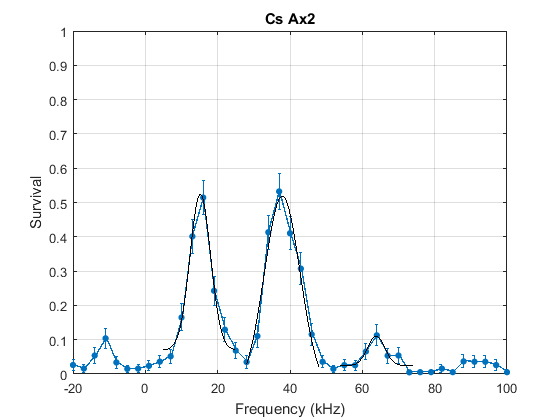

xplot = linspace( max(fitrange(1), min(xfit)), min(fitrange(2), max(xfit)), 200);
figure(4)
hold on; plot(xplot, fit_obj(xplot), '-k'); hold off;



% %% fit text on plot
% 
% xlimits = xlim;
%     s1 = ['fit to ', formula(fit_obj)];
%     [avg, err] = get_mean_error_from_fit(fit_obj);  % I don't know what this is
%     s2 = sprintf(['\n', num2str(avg)]);
%     s3 = sprintf(['\n', num2str(err)]);
%     text(xlimits(1)+(xlimits(2)-xlimits(1))/10, 0.9 - (i-1)*0.17, [s1, s2, s3])
%     legend off;

%     box on; grid on;
%     xlabel({param_name_unit}, 'interpreter','none');
%     ylabel('Survival probability');
%     ylim([0,1]);

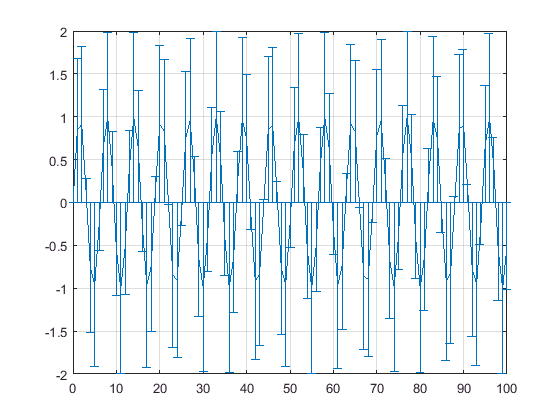

x = 0:100;
y = sin(x);
errorbar(x,y,y)

grid on